# Taller 1: 

# Método de Diseño con Root Locus 

### Eduardo Toro Bernal

### Control

### Ingeniería Electrónica 

### Universidad Nacional de Colombia

## Diseño 1: 

Deseamos diseñar un control de velocidad para un servomecanismo accionado por cinta. La función de transferencia de la corriente I(s) a la velocidad de la cinta $\Omega (s)$ (en milimetros por milisegundos por amperio) es: 

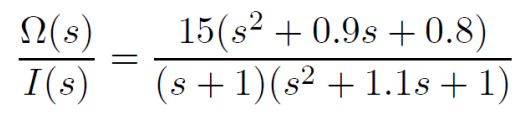

Deseamos diseñar un sistema realimentado para que la respuesta a un paso de referencia satisfaga: 

#### Solución

Como la función de transferencia no tiene polos en cero (tipo 0) debemos utilizar un controlador PI para garantizar que el error de posición sea cero. Tomando la ecuación caracteristica: 


$$\Delta (s) = 1 + CG$$


Realizando las operaciones indicadas, igualando a cero y despejando ki obtenemos: 


$$\frac{-1}{k_i}=\frac{15s^2+13.5s+12} {s^4 + (2.1+15k_p)s^3 + (2.1+13.5k_p)s^2 + (1+12k_p)s}$$


Implementamos esta función de transferencia definiendo un valor de kp por tanteo: 

kp1 = 38

kp1 = 38

Num1 = [15 13.5 12]; 
Den1 = [ 1 2.1+15*kp1 2.1+13.5*kp1 1+12*kp1 0]; 
G1 = tf(Num1,Den1) 

G1 =
 
         15 s^2 + 13.5 s + 12
  -----------------------------------
  s^4 + 572.1 s^3 + 515.1 s^2 + 457 s
 
Continuous-time transfer function.



Definimos la región de diseño: 

Mp1 = 0.05; 
zita1 = sqrt((log(Mp1)^2)/((log(Mp1)^2)+pi^2))

zita1 = 0.6901

theta1 = acosd(zita1)

theta1 = 46.3614

ts1 = 15

ts1 = 15

a1 = -4.5/ts1

a1 = -0.3000

tr1=4

tr1 = 4

wn1=1.8/tr1

wn1 = 0.4500

Ahora, aplicamos el root locus y hallamos los limites de ki en los puntos de corte que define nuestra región de diseño: 

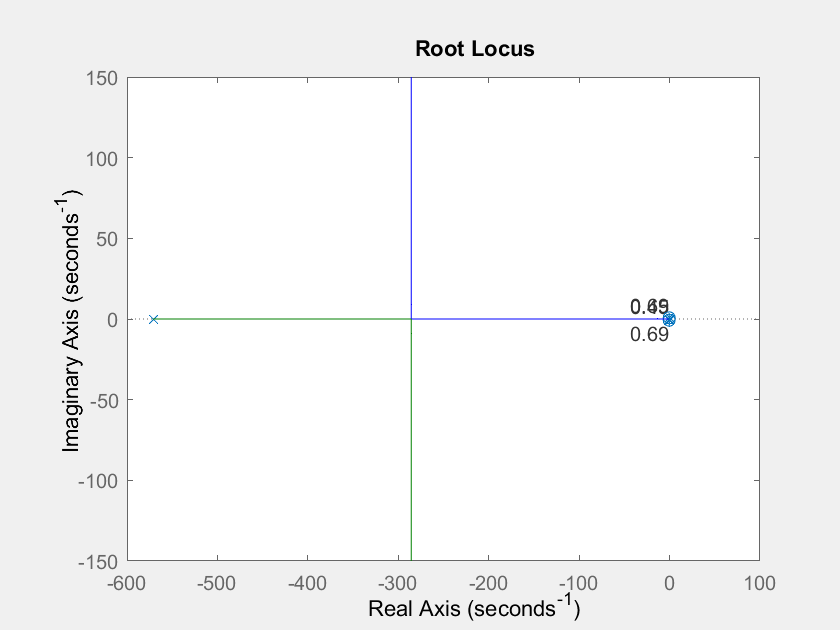

figure(1)
set(gcf,'Visible','on'); 
rlocus(G1)
hold on
sgrid(zita1,wn1)
tsline1=-4.5/ts1+(-5:1.5:5)*1i;
plot(tsline1)
hold off

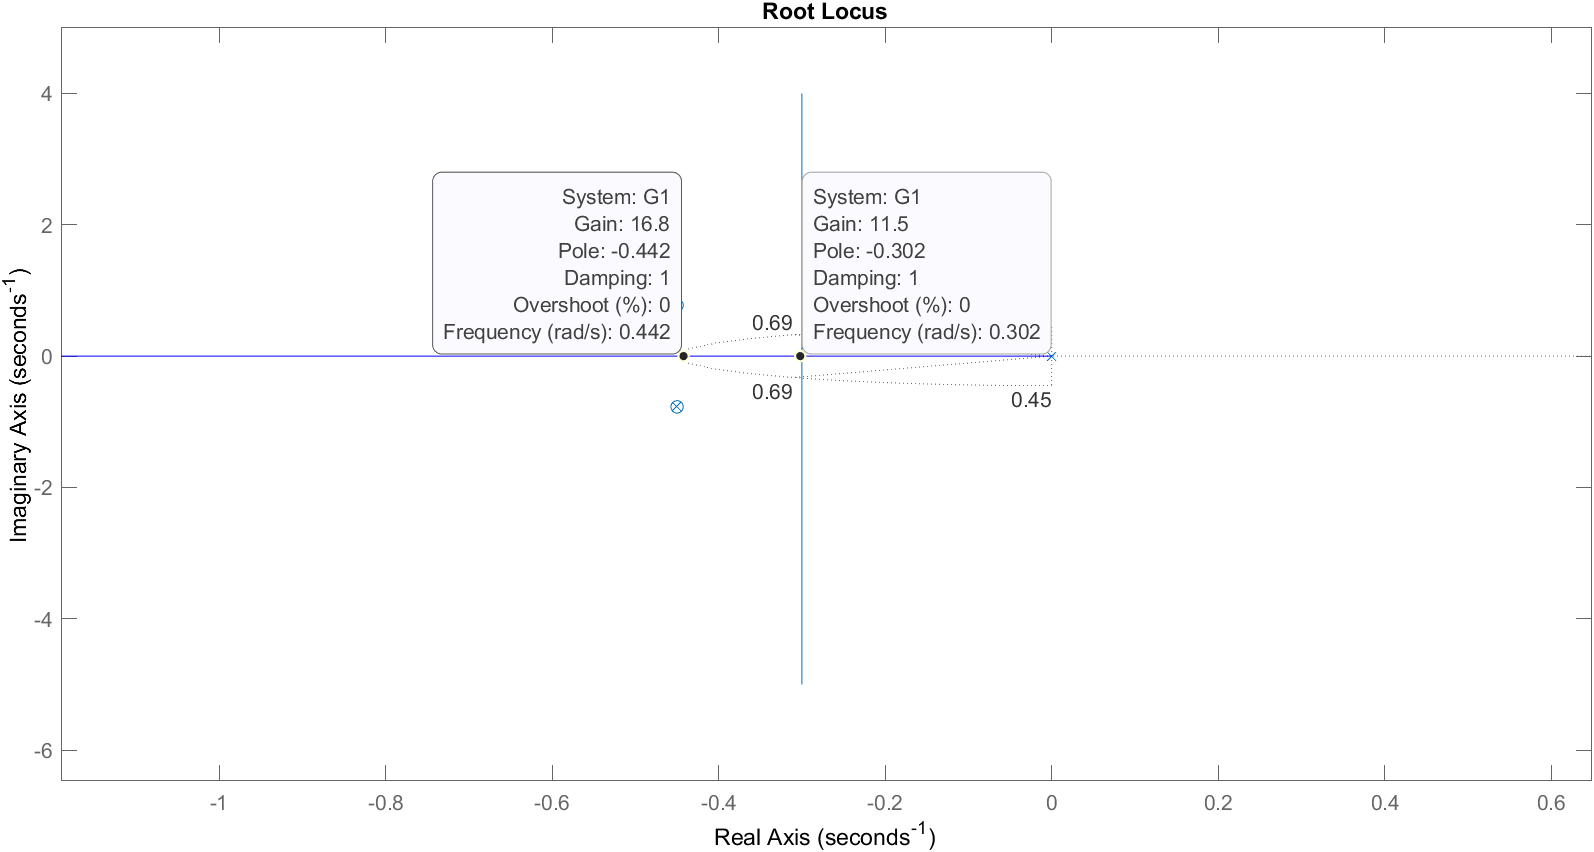

Obtuvimos que: $11.5 \leq k_i \leq 16.8$

Por último, probamos el diseño del controlador ante una entrada paso: 

ki1 = 16

ki1 = 16

Goriginal1 = tf(15*[1 0.9 0.8], [1 2.1 2.1 1])

Goriginal1 =
 
    15 s^2 + 13.5 s + 12
  -------------------------
  s^3 + 2.1 s^2 + 2.1 s + 1
 
Continuous-time transfer function.



Controlador1 = tf([kp1 ki1], [1 0])

Controlador1 =
 
  38 s + 16
  ---------
      s
 
Continuous-time transfer function.



G01 = feedback(Controlador1*Goriginal1,1)

G01 =
 
       570 s^3 + 753 s^2 + 672 s + 192
  -----------------------------------------
  s^4 + 572.1 s^3 + 755.1 s^2 + 673 s + 192
 
Continuous-time transfer function.



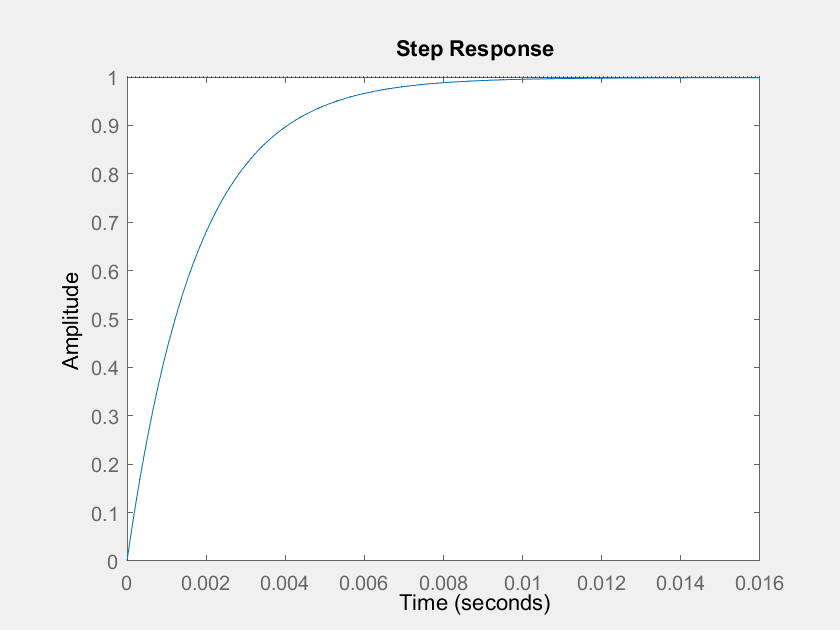

step(G01)

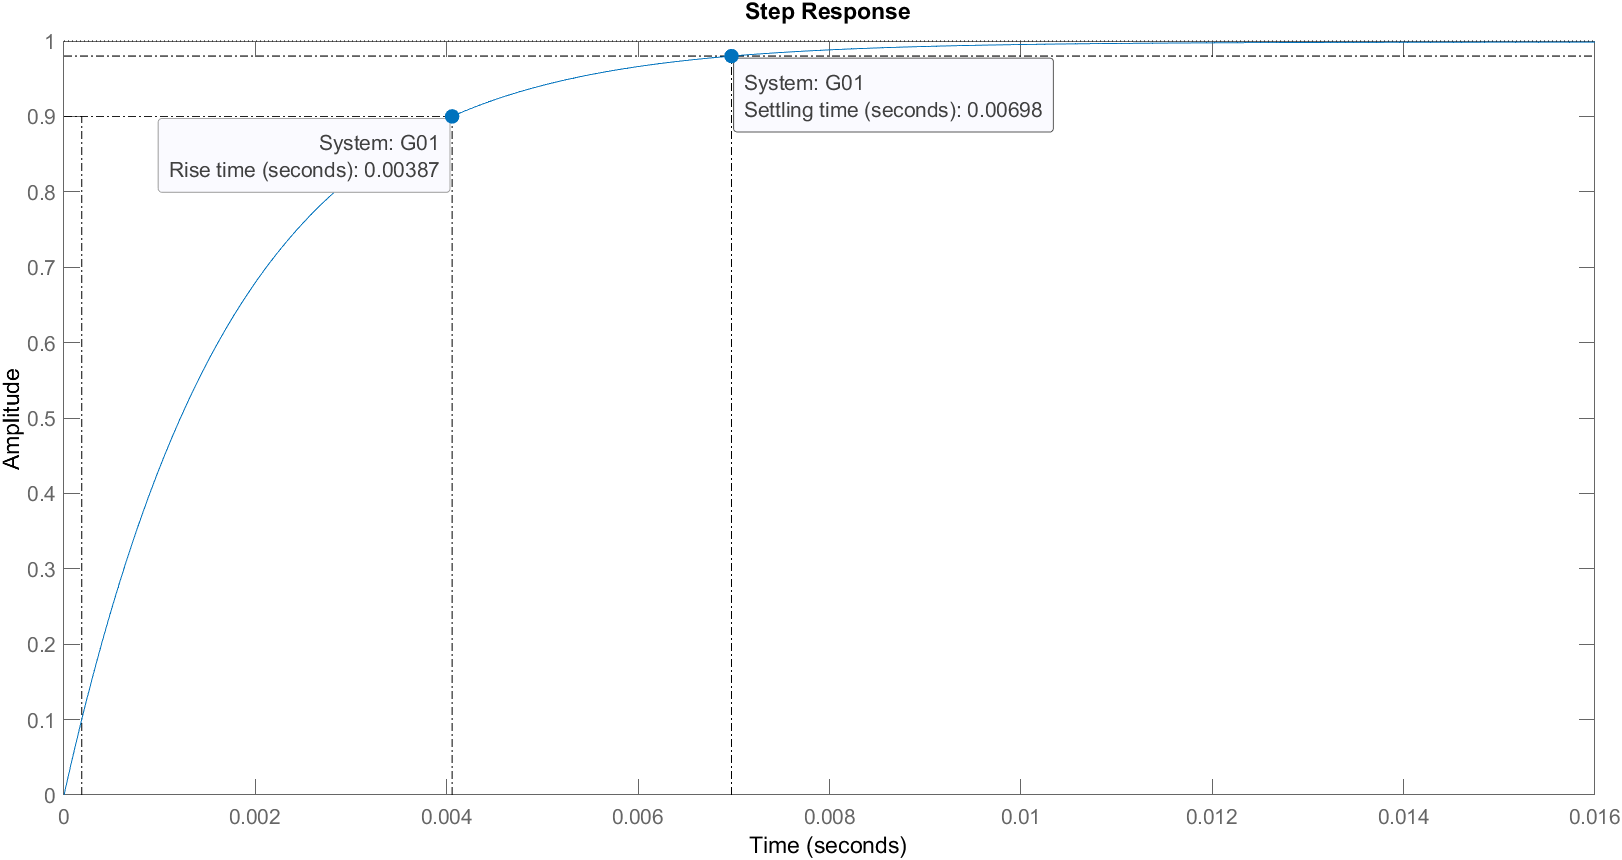

Se puede observar que todos los criterios del diseño fueron cumplidos ya que: 

tr = 3.87 ms

ts = 6.98  ms

El sobrepico es despreciable ya que la ganancia seleccionada ubica los polos en el eje real. 

## Diseño 2: 

Considere la planta con función de transferencia: 

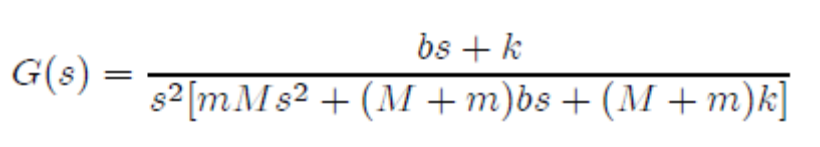

Para ser puesta en un sistema de realimentación unitaria. Esta es la función de transferencia que relaciona la fuerza de entrada u(t) y la posición de la masa M en el problema del sensor y actuador no controlados. 

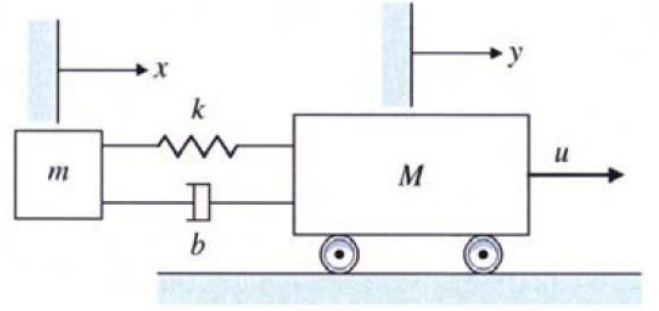

Diseñe un controlador D(s) para que la respuesta al paso en lazo cerrado tenga un tiempo de elevación menor que 0.1 s y un sobrepico menor al 10%. 

### Punto a)

Aproxime G(s) asumiendo que m=0, M=1, k=1, b=0.1 y D(s) = K. 

¿Puede escoger K para satisfacer las especificaciones de diseño?¿Por qué?

#### Solución a) 

La función de transferencia queda: 

m = 0

m = 0

M = 1

M = 1

k = 1

k = 1

b = 0.1

b = 0.1000

Num2 = [b k]

Num2 =     0.1000    1.0000


Den2 = [M*m (M+m)*b (M+m)*k 0 0]

Den2 =          0    0.1000    1.0000         0         0


Goriginal2 = tf(Num2, Den2)

Goriginal2 =
 
    0.1 s + 1
  -------------
  0.1 s^3 + s^2
 
Continuous-time transfer function.



Teniendo en cuenta la especificaciones dadas: 

Mp2 = 0.1; 
zita2 = sqrt((log(Mp2)^2)/((log(Mp2)^2)+pi^2))

zita2 = 0.5912

theta2 = acosd(zita2)

theta2 = 53.7610

tr2=0.1

tr2 = 0.1000

wn2=1.8/tr2

wn2 = 18

Hallamos el root locus de la FT y observamos los puntos de corte: 

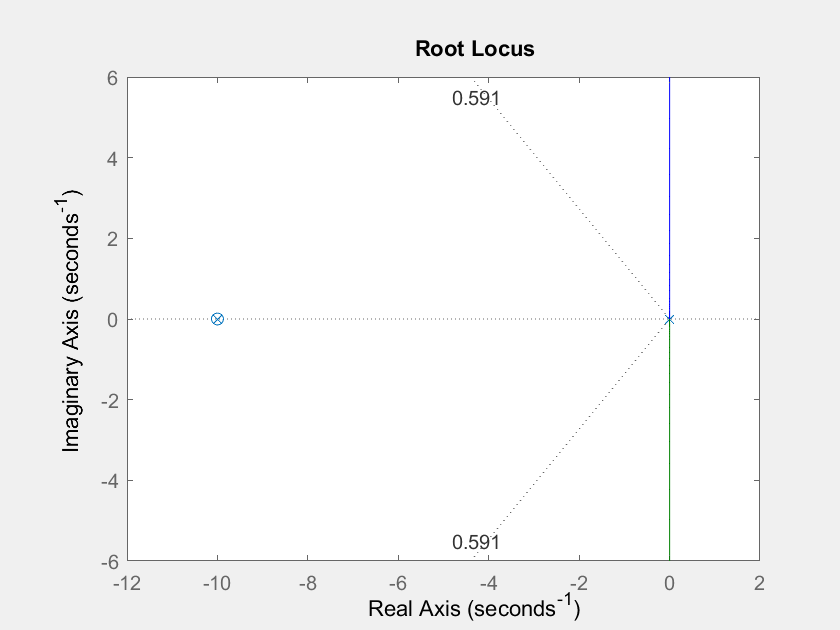

figure(2)
set(gcf,'Visible','on'); 
rlocus(Goriginal2)
sgrid(zita2, wn2)

Observamos que factorizando la FT se cancela un cero con un polo y por ende, nos quedan dos polos ubicados en cero. Observando el root locus, NO podemos escoger ningun K que quedé dentro de la región de diseño, por lo cual no se cumpliran las condiciones dadas. 

### Punto b)

Repetir el punto a) asumiendo que D(s) = K(s+a), y muestre que K y "a" pueden ser seleccionados para encontrar las especificaciones. 

#### Solución

Tomando la ecuación característica del sistema y despejando el valor de "k2" obtenemos: 


$$\frac{0.1s^2+(1+0.1a)s+a}{0.1s^3+s^2}=\frac{-1}{k_2}$$


Aplicando root locus a esta función de transferencia: 

a = 5

a = 5

Num02 = [0.1 1+0.1*a a]

Num02 =     0.1000    1.5000    5.0000


Den02 = [0.1 1 0 0]

Den02 =     0.1000    1.0000         0         0


G02 = tf(Num02,Den02)

G02 =
 
  0.1 s^2 + 1.5 s + 5
  -------------------
     0.1 s^3 + s^2
 
Continuous-time transfer function.



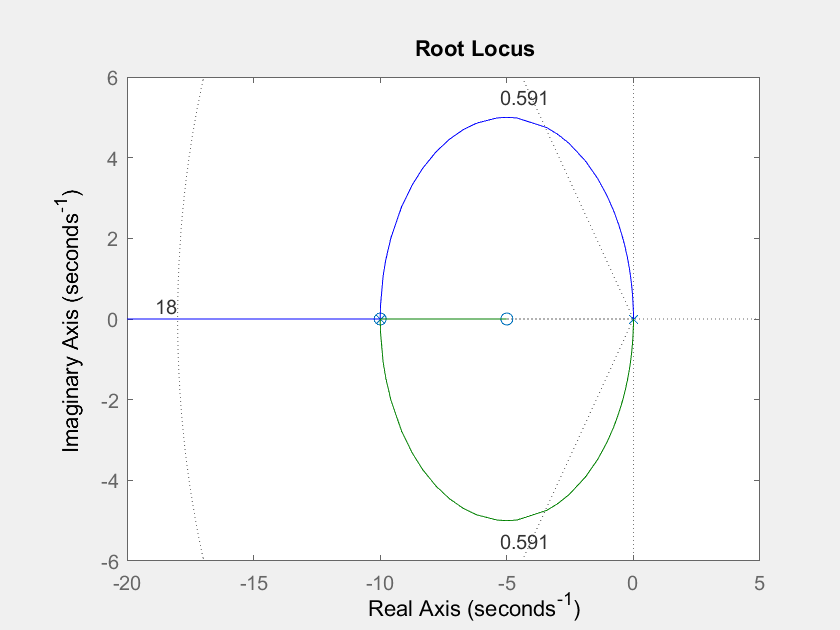

figure(3)
set(gcf,'Visible','on'); 
rlocus(G02)
sgrid(zita2, wn2)

 Por ende obtenemos que  6.89$\leq k_2 \leq $25

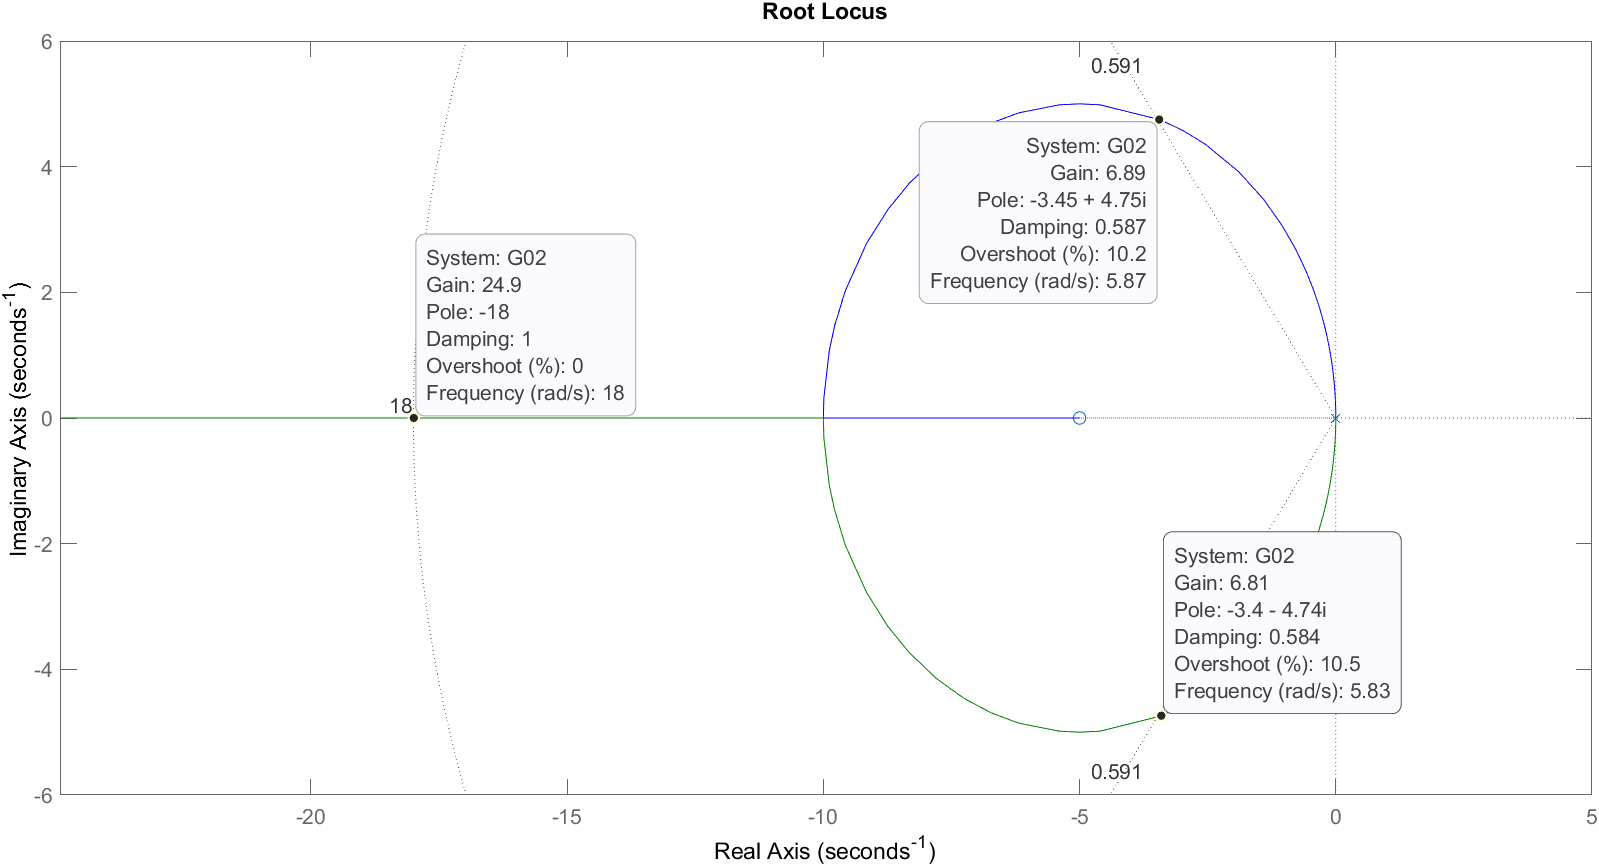

Sin embargo, debido a la presencia del zero, root locus pierde precisión por lo que podemos extendernos un poco más de dichos limites por medio de tanteo. 

Por último, comprobamos con la respuesta al paso: 

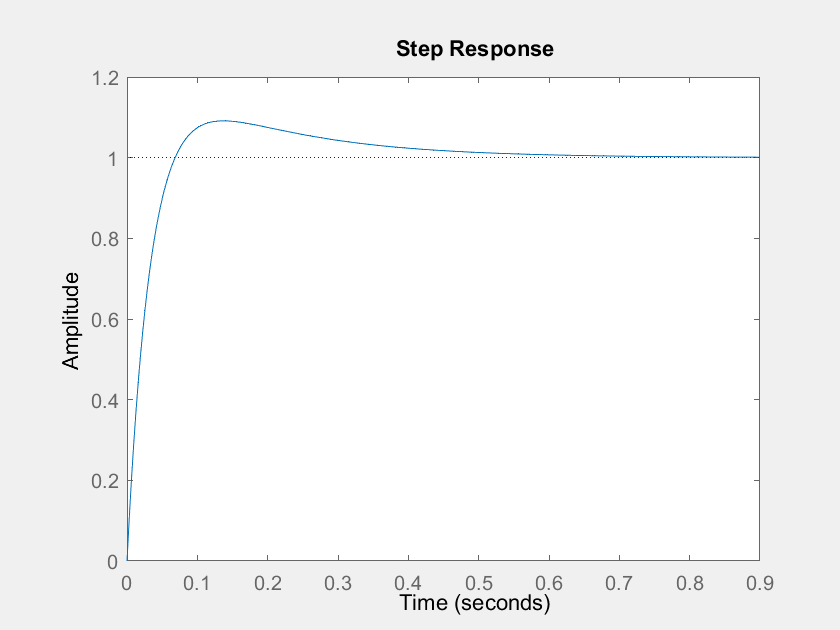

k2=35; 
Goriginal2 = tf(Num2, Den2);
Controlador2= tf(k2*[1 a], 1); 
G002 = feedback(Controlador2*Goriginal2,1); 
step(G002)

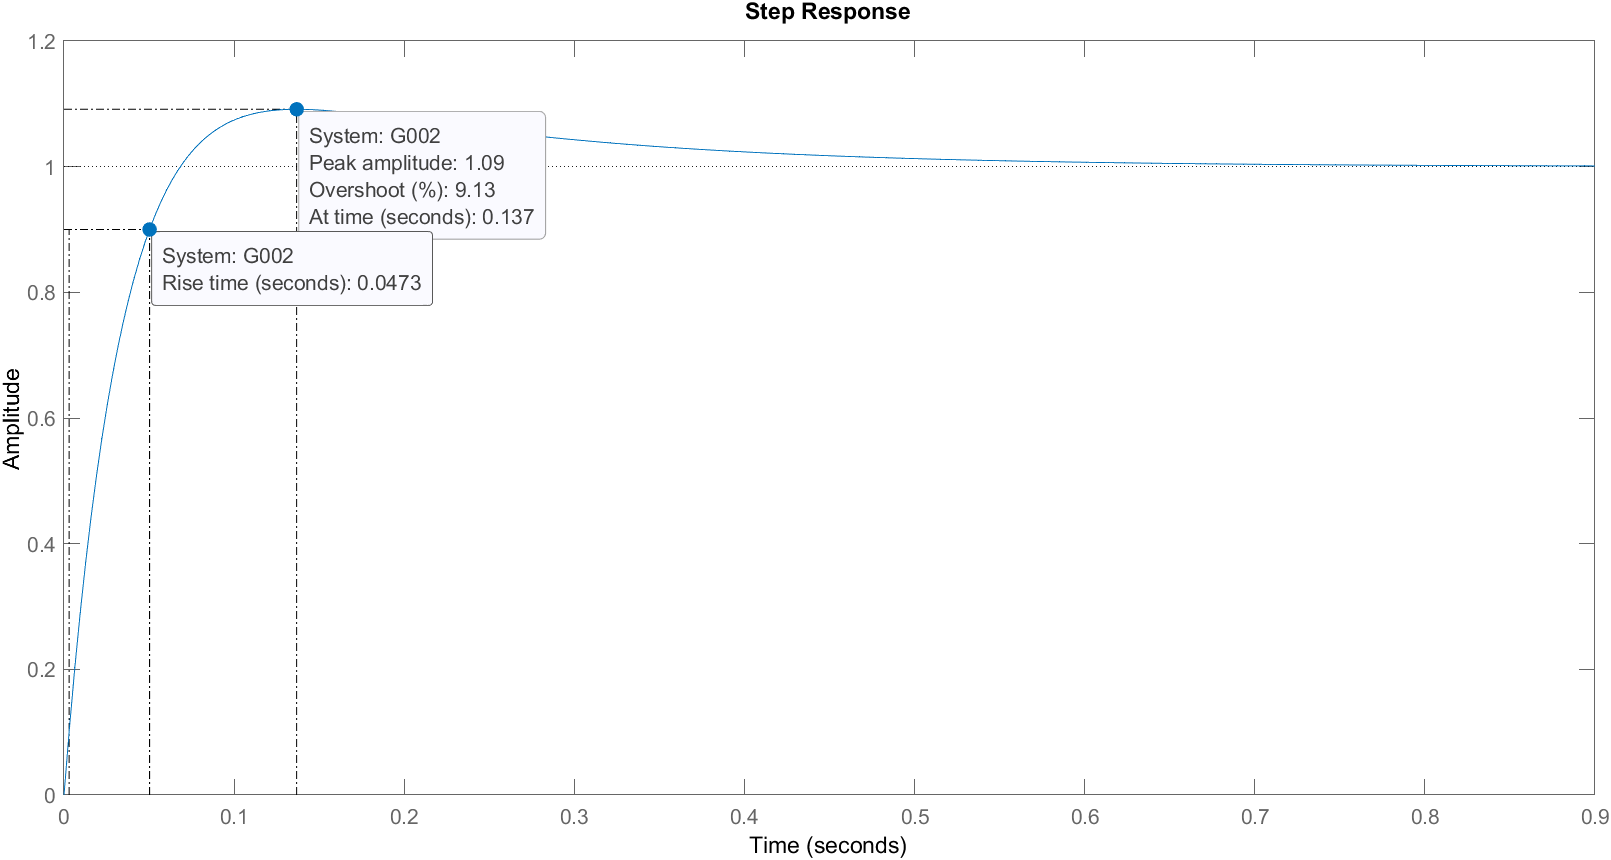

Se puede observar que todos los criterios del diseño fueron cumplidos ya que: 

tr = 0.04 s 

Mp = 9.13 %

### Punto c)

Repita el punto b) con un controlador práctico dado por la función de transferencia D(s) = k*p(s+z)/(s+p) y seleccione p para que los valores de de K y a calculados en el punto b) permanezcan más o menos validos. 

#### Solución

Tomando el k2 = 35 y a = 5 (hallados en el item anterior) la función de transferencia del controlador es: 


$$D(s) = \frac{35*p(s+5)}{s+p}$$


Tomando la ecuación caracteristica, igualando a cero y despejando P, obtenemos: 


$$\frac{s^2+35s+175}{s^3}=\frac{-1}{p}$$


A esta función de transferencia la hallamos el root locus: 

Num3 = [1 35 175]

Num3 =      1    35   175


Den3 = [1 0 0 0]

Den3 =      1     0     0     0


G3 = tf(Num3,Den3)

G3 =
 
  s^2 + 35 s + 175
  ----------------
        s^3
 
Continuous-time transfer function.



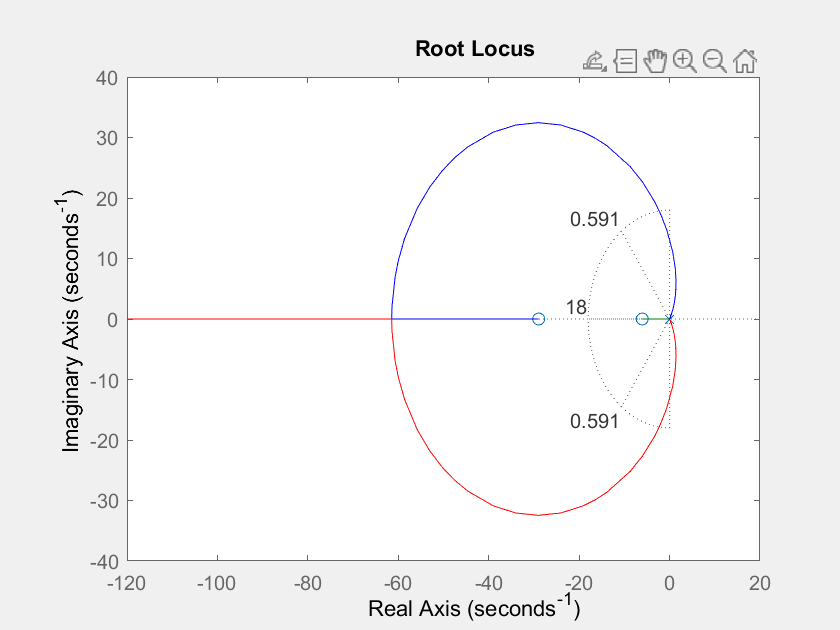

figure(4)
set(gcf,'Visible','on'); 
rlocus(G3)
sgrid(zita2, wn2)

Se puede observar, debemos tener cuidado con el valor de la ganancia para que mantener estable el sistema. Además, siguiendo esta condición no encontramos ningún polo de la linea roja ni azul dentro de la zona de diseño pero, como se explico anteriormente, debido a la presencia de ceros la precisión de root locus disminuye: $4.97 < p$

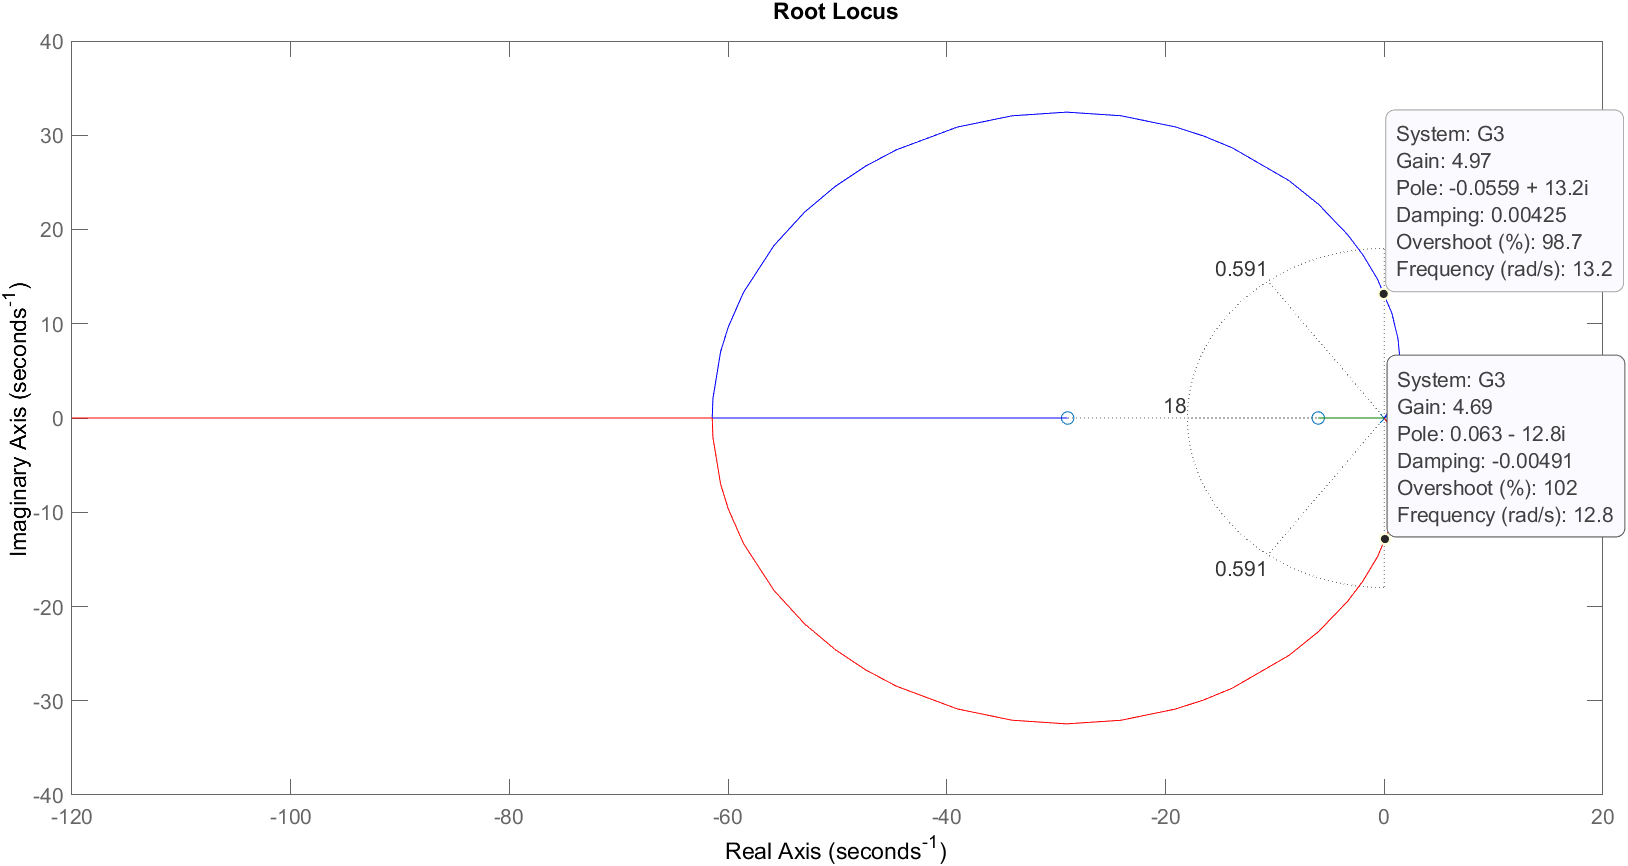

Por medio de tanteo se determino que: 

p = 100

p = 100

Controlador02= tf(k2*p*[1 a], [1 p])

Controlador02 =
 
  3500 s + 17500
  --------------
     s + 100
 
Continuous-time transfer function.



G03 = feedback(Goriginal2*Controlador02,1)

G03 =
 
           350 s^2 + 5250 s + 17500
  -------------------------------------------
  0.1 s^4 + 11 s^3 + 450 s^2 + 5250 s + 17500
 
Continuous-time transfer function.



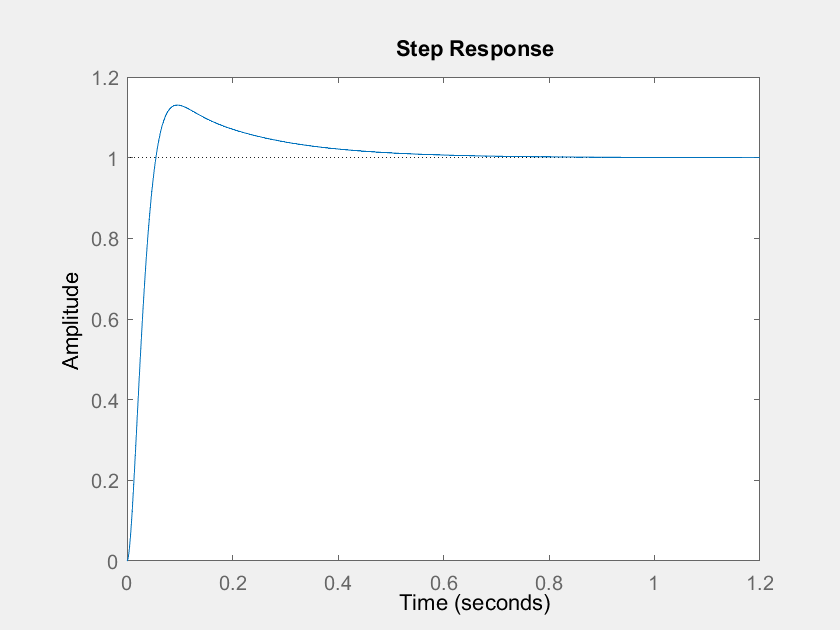

step(G03)

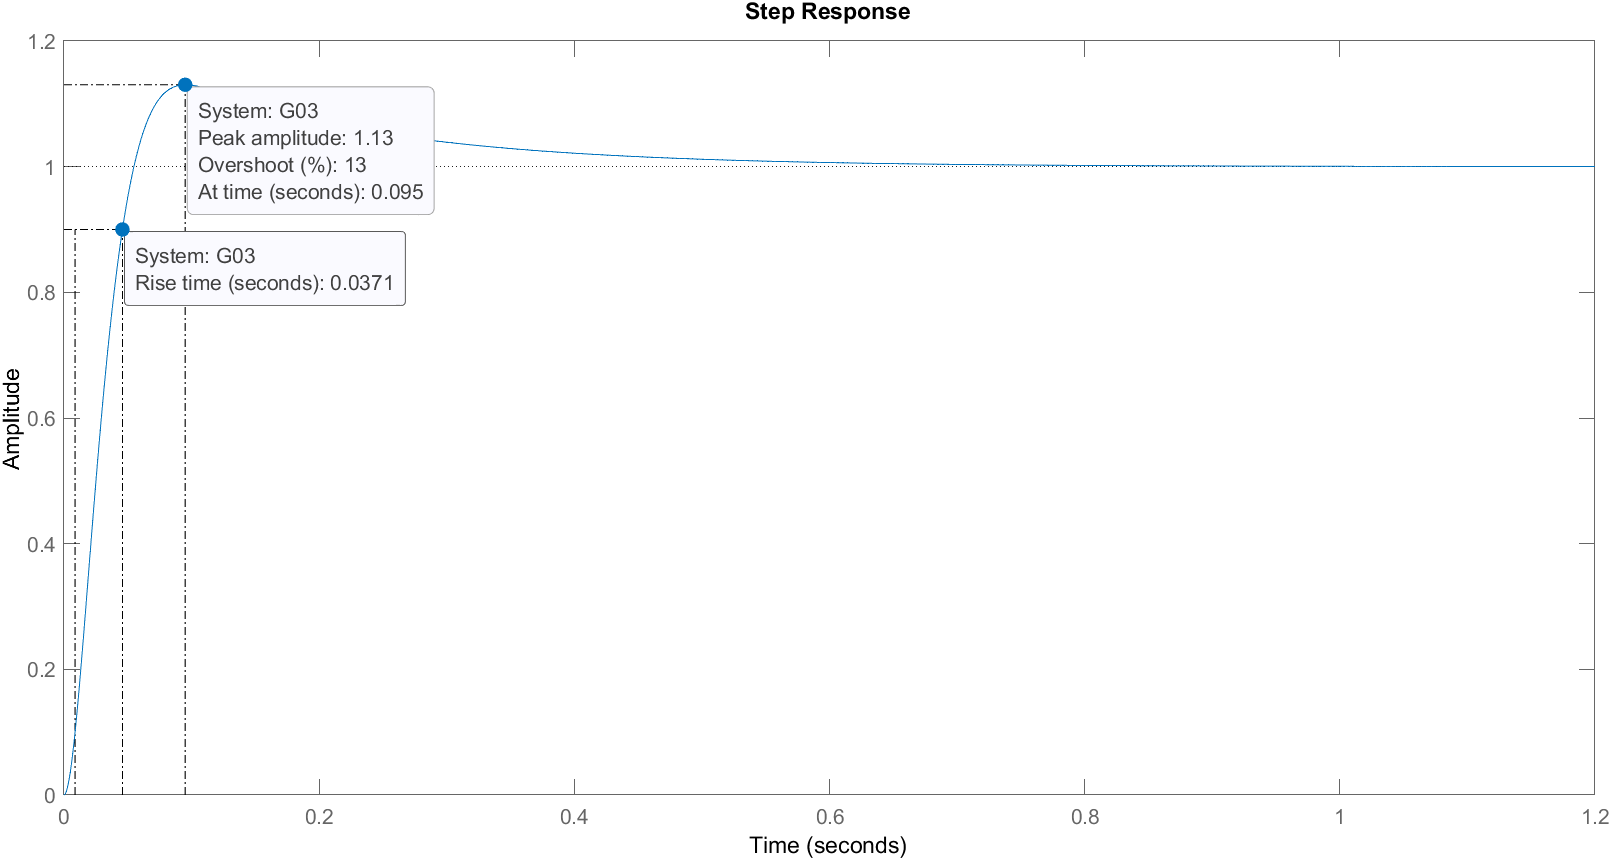

Los criterios de diseño son más o menos alcanzados: 

tr = 0.037 s 

Mp = 13%

Es importante aclarar que sí aumentamos aun más la ganancia p, los criterios serán alcanzados satisfactoriamente pero a la hora de implementar en la vida real será mucho más dificil. 

## Diseño 3

Un servomecanismo de posicionamiento de una máquina herramienta de control numérico tiene normalizada y escalada su función de transferencia dada por: 


$$G(s) = \frac{1}{s(s+1)}$$


Las especificaciones de diseño requieren que, en la configuración de realimentación unitaria, los polos de lazo cerrado estén ubicados en $s=-1\pm j*\sqrt3$

### Punto a)

Muestre que está especificación no puede ser alcanzada sí solamente seleccionamos un control proporcional $D(s)=K_p$ . 

#### Solución

Tomando la ecuación caracteristica del sistema (donde se encuentran los polos de lazo cerrado): 


$$\Delta(s)=1 +CG$$



$$\Delta (s) = s^2 +s +k_p$$


Ubicando los polos dados: 


$$s_1=-1+j\sqrt3$$



$$0=(-1+j\sqrt3 )^2+(-1+j\sqrt3)+k_p$$



$$0=-3-j\sqrt3+k_p$$



$$k_p=3+j\sqrt3$$


Para ubicar el segundo polo, se observa que son polos conjugados por lo que: 


$$k_p=3-j\sqrt3$$


Por lo que llegamos a una incongruencia ya que kp no puede tomar dos valores al mismo tiempo. 

### Punto b)

Diseñe un compensador $D(s)=\frac{K*(s+z)}{s+p}$ que cumpla con la especificación. 

#### Solución

Para ubicar los polos de lazo cerrado tomamos la ecuación caracteristica: 


$$\Delta(s)=1+CG$$


Operando y simplificando se obtiene: 


$$\Delta(s) = s^3 +(1+p)s^2+(p+k)s+kz$$


Ahora ubicamos los polos reemplazandolos donde observemos 's': 

Para $s_1 = -1+j\sqrt3$ tenemos: 


$$\Delta(s) = (-1+j\sqrt3)^3 +(1+p)(-1+j\sqrt3)^2+(p+k)(-1+j\sqrt3)+kz$$


Igualando a cero y simplificando obtenemos la primera ecuación: 


$$6-2\sqrt3j+(-3-\sqrt3j)p+(-1+\sqrt3j)k+kz=0$$
 

Para el segundo polo, al ser conjugado del anterior obtenemos la segunda ecuación: 


$$6+2\sqrt3j+(-3+\sqrt3j)p+(-1-\sqrt3j)k+kz=0$$


Despejando z de la segunda ecuación obtenemos la tercera ecuación: 


$$z=\frac{-6-2\sqrt3j-(-3+\sqrt3j)p-(-1-\sqrt3j)k}{k}$$


Reemplazando la tercera ecuación en la primera y simplificando, obtenemos: 


$$p=-2+k
$$


Reemplazando este resultado en la tercera ecuación y simplificando, obtenemos: 


$$z=\frac{-12+4k}{k}$$


Con estos resultados, la función de transferencia del controlador queda: 


$$D(s)=\frac{k*(s+(\frac{-12+4k}{k}))}{s+(-2+k)}$$


Ahora vamos a implementar la planta y el controlador junto con un k constante para observar la ubicación de los polos: 

G4 = tf([1], [1 1 0]) 

G4 =
 
     1
  -------
  s^2 + s
 
Continuous-time transfer function.



k4 = 12 

k4 = 12

C4 = tf([k4 -12+4*k4], [1 -2+k4])

C4 =
 
  12 s + 36
  ---------
   s + 10
 
Continuous-time transfer function.



G04 = feedback(C4*G4,1)

G04 =
 
         12 s + 36
  ------------------------
  s^3 + 11 s^2 + 22 s + 36
 
Continuous-time transfer function.



Comprobamos los polos:

roots([1 11 22 36])

ans =   -9.0000 + 0.0000i
  -1.0000 + 1.7321i
  -1.0000 - 1.7321i
